# 2D Orbit Plotting Example

## Initialize Orbits

AU = 149597898; % [km]
mu_sun = 132712440017.99; % [km3 / s2]
mu_tatooine = 320000; % [km3 / s2]
r_tatooine = 6070; % [km]
h_tatooine_initial = r_tatooine + 1000;
h_tatooine_final = r_tatooine + 150

h_tatooine_final = 6220


a_kuat = 0.6 * AU; % [km]
e_kuat = 0;
% Create a true anomaly vector from 0 to 180 degrees with 100 elements
thetastar_kuat = linspace(0, deg2rad(180), 100);
w_kuat = 0;

a_t = 4.5 * AU; % [km]
e_t = 0;
% Create a true anomaly vector from 0 to 270 degrees with 300 elements
thetastar_t = linspace(0, deg2rad(270), 300);
w_t = deg2rad(90);

% Example transfer
r_p_trans = 0.6 * AU;
r_a_trans = 4.7 * AU;
a_trans = (r_p_trans + r_a_trans) / 2;
e_trans = r_a_trans / a_trans - 1;
p_trans = a_trans * (1 - e_trans ^ 2);
% Rearrange orbit equation to get true anomaly when transfer orbit is at Kuat
thetastar_trans_0 = acos(1 / e_trans * (p_trans / a_kuat - 1));
% Rearrange orbit equation to get true anomaly when transfer orbit is at t
thetastar_trans_f = acos(1 / e_trans * (p_trans / a_t - 1));
% Create true anomaly array for transfer orbit
thetastar_trans = linspace(thetastar_trans_0, thetastar_trans_f, 100);
w_trans = w_kuat - thetastar_trans_0;


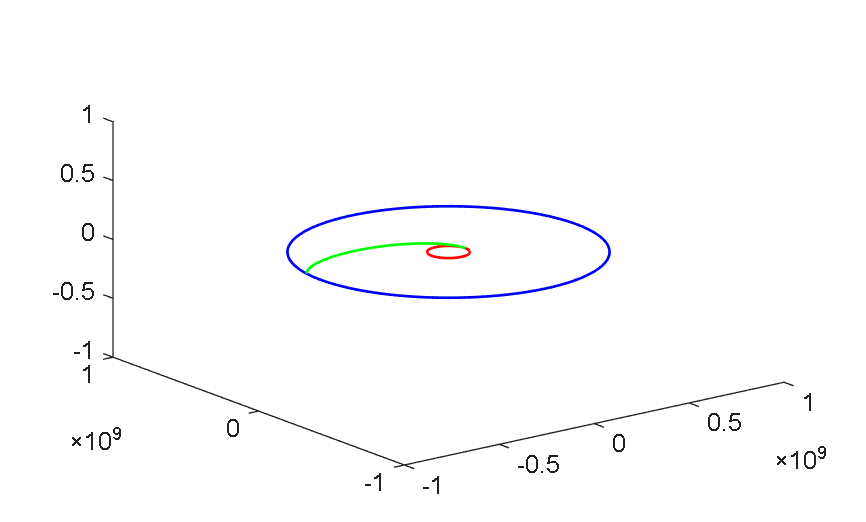

h = sqrt(mu_sun * p_trans);
v_kuat = sqrt(mu_sun/a_kuat);
v_plus = sqrt(mu_sun*(2/a_kuat - 1/a_trans));
gamma1 = acosd(h/(a_kuat*v_plus));
v_inf1 = sqrt(v_plus^2 + v_kuat^2 - 2 * v_plus * v_kuat * cosd(gamma1));
v_tatooine = sqrt(mu_sun/a_kuat);
e = 1 + h_tatooine_initial * (v_inf1^2/mu_tatooine);
a = -mu_tatooine/v_inf1^2;
v_minus = sqrt(mu_sun * (2/a_t - 1/a_trans));
gamma2 = acosd(h/(a_t * v_minus));
v_inf2 = sqrt(v_minus^2 + v_tatooine^2 - 2 * v_minus * v_tatooine * cosd(gamma2));
plotOrbit3(0, 0, 0, a_kuat, 0, linspace(0, 2*pi, 100), 'r', 1, 1, [0, 0 , 0],0,1);
plotOrbit3(0, 0, 0, a_t, 0, linspace(0, 2*pi, 100), 'b', 1, 1, [0, 0, 0],0,1);
plotOrbit3(0, 0, 0, a_trans*(1-e_trans^2), e_trans, thetastar_trans, 'g', 1, 1, [0, 0, 0],0,1)
hold off

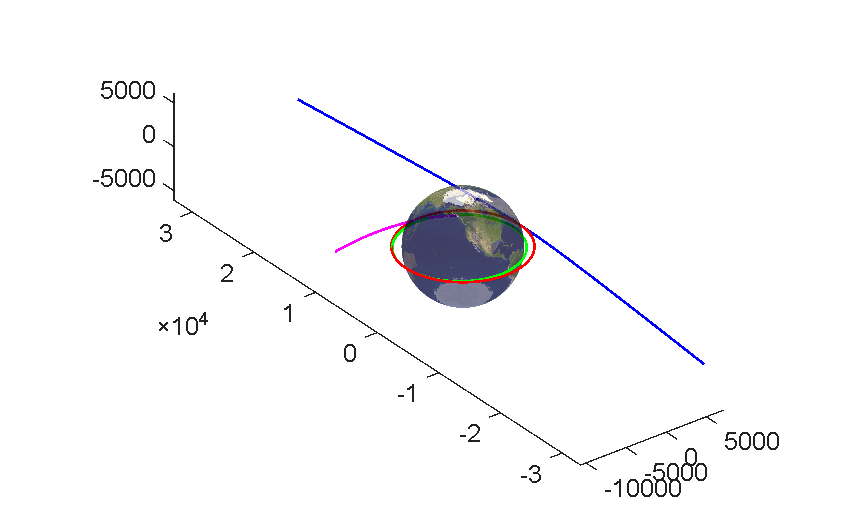

v_tatooine_orbit = sqrt(mu_tatooine/h_tatooine_initial);
a_trans_orbit = (h_tatooine_initial + h_tatooine_final)/2;
v_tatooine_transfer = sqrt(mu_tatooine*(2/h_tatooine_initial - 1/a_trans_orbit));
deltav = v_tatooine_transfer - v_tatooine_orbit;
e_orbit = 1 - h_tatooine_final/a_trans_orbit;
plotOrbit3(0, 0, 0, a_trans_orbit*(1-e_orbit^2), e_orbit, linspace(0, 2*pi, 100), 'g', 1, 1, [0, 0, 0],0,1); hold on
plotOrbit3(0, 0, 0, h_tatooine_initial, 0, linspace(0, 2*pi, 100), 'r', 1, 1, [0, 0, 0],0,1); 
plotOrbit3(0, 0, 0, a*(1-e^2), e, linspace(-pi/2.2, pi/2.2, 100), 'b', 1, 1, [0, 0, 0],0,1);
v_inf_dept = v_infi;
e_dept = 1 + h_tatooine_final*v_inf_dept^2/mu_tatooine;
a_dept = -mu_tatooine/v_inf_dept^2;
plotOrbit3(1, 0, 0, a_dept*(1-e_dept^2), e_dept, linspace(0, pi/2, 100), 'm', 1, 1, [0, 0, 0],0,1); 
earthy(r_tatooine, "Earth", 0.5, [0,0,0])
axis equal
hold off

## Plot

% % Plot Kuat
% orbitplot2D(a_hyp, e, deg2rad(linspace(-100, 100, 1000)), w_kuat, "Kuat", r_scale = AU);
% % Plot t
% orbitplot2D(a_t, e_t, thetastar_t, w_t, "Tatooine", r_scale = AU, LineStyle = "-")
% % Plot transfer
% orbitplot2D(a_trans, e_trans, thetastar_trans, w_trans, "Transfer", r_scale = AU, LineStyle = "-.", origin = [0; 0])
% hold off
% grid on
% axis equal
% title("Plot of Transfer between Kuat and Tatooine Orbits")
% xlabel("X [AU]")
% ylabel("Y [AU]")
% 
% legend()
% plotOrbit3(0, 0, 0, a_kuat, 0, [0, 2*pi], 'r', 1, 1, [0, 0, 0],0,)